# 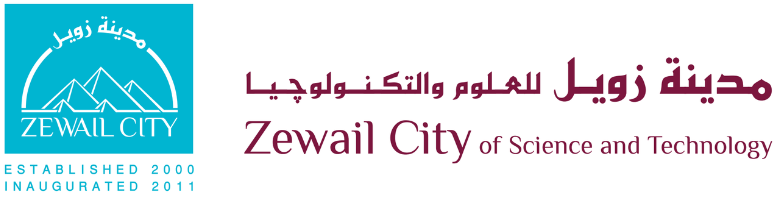

# **CIE 425 Assignment 4**

## **Mariam Elseedawy         201901281**

## **Jihad Masood                 201902204**

### **Question:**

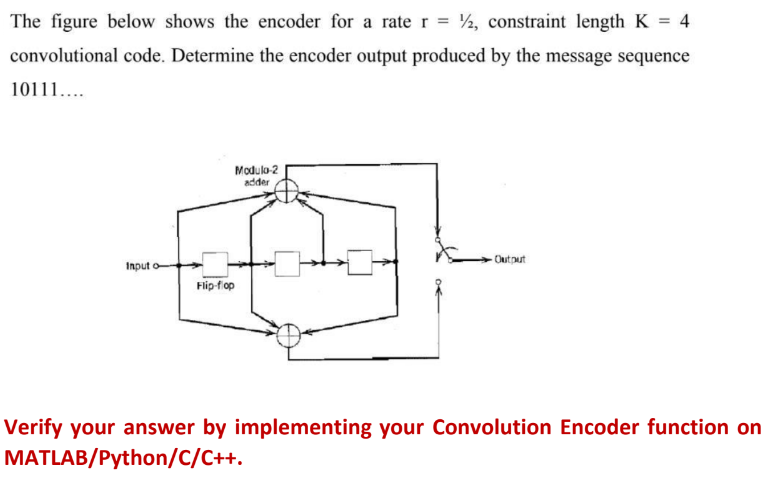

### **Answer:**

#### **Hand analysis:**

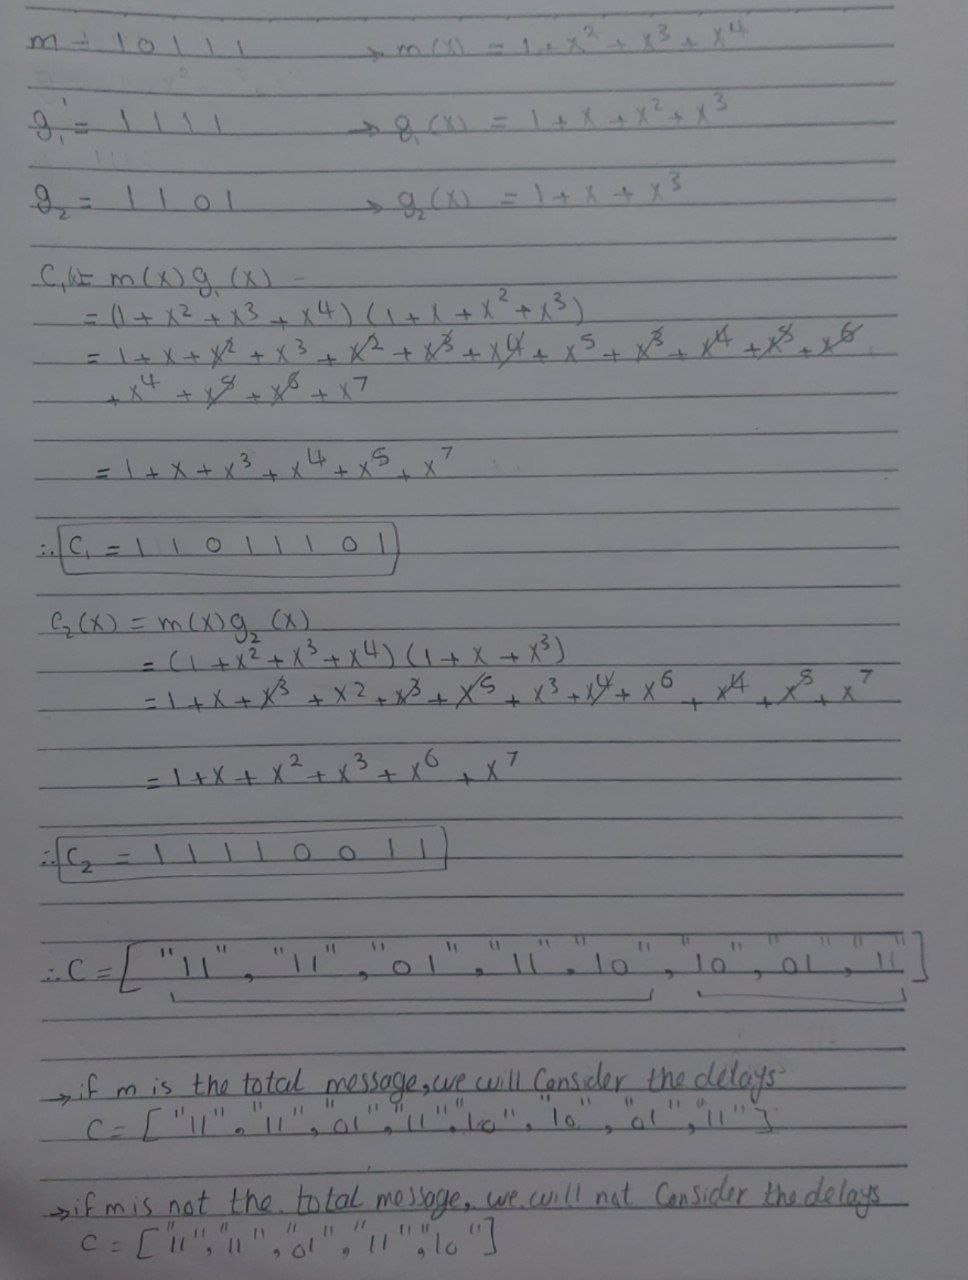

#### **Code implementation:**

clc
clear

%inputs
m = [1 0 1 1 1];
g1 = [1 1 1 1];
g2 = [1 1 0 1];
r = 1/2;
%Notes: k = 4 -> 3 delays

%utput after applying the convolution coding
c_final = convolution_coding(m,g1,g2);

%printing the output
%If m is the total message, we will consider the delays
fmt=['Output: ' repmat(' %s ',1,numel(c_final)) '\n'];
fprintf(fmt,c_final);

Output:  11  11  01  11  10  10  01  11 


%If m is not the total message, we will not consider the delays
m_length = length(m);
required_length = 1/r*m_length/2;
fmt=['Output: ' repmat(' %s ',1,numel(c_final(1:required_length))) '\n'];
fprintf(fmt,c_final(1:required_length));

Output:  11  11  01  11  10 


Comment: hand analysis results is the same as code results.

**Functions [used in the code]**

function equation_array = get_polynomial(bits_array)
%This function gets the polynomial function of stream of bits
%input: array of bits as integers (0s, 1s)
%output: polynomial function

syms x;
equation_array = [];
bits_length = length(bits_array);
for i = 1:bits_length
    if (bits_array(i) == 0)
        equation_array = [equation_array 0];
    else
        temp = x^(i-1);
        equation_array = [equation_array temp];
    end
end
end


function coefficients = get_coefficients(m_x,g_x)
%This function gets the coeffiecints of an equation resulted from multiplication of two polynomial equations
%input: two polynomial equations
%output: array of integer coeffiecints

m_x_length = length(m_x);
g1_x_length = length(g_x);
c_x_array = [];
for i = 1:m_x_length
    for j = 1:g1_x_length
        temp = m_x(i)*g_x(j);
        c_x_array = [c_x_array temp];
    end
end
mult_equation = sum(c_x_array);
coefficients_flipped = sym2poly(mult_equation);
coefficients = fliplr(coefficients_flipped);
end


function c_bits_array = get_bits(c_coefficients)
%This function apply xor process (usong mod2) on a ploynomial equation using its coefficients
%input: array of integer coeffiecints
%output: array of integer (0s, 1s)

c_coefficients_length = length(c_coefficients);
c_bits_array = [];
for i = 1:c_coefficients_length
    if (mod(c_coefficients(i),2) == 0)
        c_bits_array = [c_bits_array 0];
    else
        c_bits_array = [c_bits_array 1];
    end
end
end


function c_final = get_final_output(c1_bits_array, c2_bits_array)
%This function create the final output using its 2 parts
%input: 2 arrays of integer coeffiecints
%output: array of strings

c_final = [];
c12_length = length(c1_bits_array);
for i = 1:c12_length
    temp = append(int2str(c1_bits_array(i)),int2str(c2_bits_array(i)));
    c_final = [c_final string(temp)];
end
end

function c_final = convolution_coding(m,g1,g2)
%This function apply convolution coding for a message with 2 generating functions
%input: 3 arrays of integers (0s, 1s)
%output: array of strings

m_x = get_polynomial(m);
g1_x = get_polynomial(g1);
g2_x = get_polynomial(g2);

c1_coefficients = get_coefficients(m_x,g1_x);
c2_coefficients = get_coefficients(m_x,g2_x);

c1_bits_array = get_bits(c1_coefficients);
c2_bits_array = get_bits(c2_coefficients);

c_final = get_final_output(c1_bits_array, c2_bits_array);
end